# Notes regarding lab format

We will use Matlab Livescript for this lab. Livescript allows switching between text and code cells. 

You will find the entire lab manual in this file. Some exercises require you to write a text answer, others require you to write code. You should not define functions inside this file. Instead save functions to the functions folder and call them from the code cells in this notebook.

Your finished lab report should be a .zip-file containing the data folder, your functions folder and this livescript file. As usual, you should also provide a pdf of the result of running the live script (in the Live Editor, you can **export to pdf** under Save) where all result images should be visible.

Since we need to access the functions and data folder the first step is to add these two locations MATLAB's path.

addpath('./functions');
addpath('./data');

# **Lab 4 - Triangulation**

## **Using RANSAC**

This whole lab is basically concerned with the camera equation


$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\lambda u=P\;U$$


For the uncalibrated case, $u$ is a 3-vector with the coordinates of a point in the image (and an added 1)


$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;u=\left\lbrack \begin{array}{c}
x\\
y\\
1
\end{array}\right\rbrack$$


and $U$ is a 4-vector containing the coordinates of the corresponding 3D point along with a 1 in its last element. A function

sigma = 0.5;
[Ps, us, U_true] = triangulation_test_case(sigma)

Ps = 1×2 cell array
    {3×4 double}    {3×4 double}


us =  -112.7518  425.2570
    8.2058  230.4404


U_true =     0.8147
    0.9058
    0.1270


is provided for creating a simple test case where you know the correct answer (`U_true`). Gaussian noise of standard deviation `sigma` is added to the image points. Use this example to evaluate your minimal solver.

**Ex 4.1**     Make a minimal solver for the triangulation problem, that is, a function 

U = minimal_triangulation(Ps, us)

U =     0.8163
    0.9067
    0.1347


mean((U - U_true).^2)

ans = 2.1215e-05

that takes two camera matrices, `Ps`, and two image points, `us`, and triangulates a 3D point. The image points are a 2 x 2 array whereas the camera matrices is a cell list with one camera matrix in each cell. 

Recall that $\lambda$ is the *depth*. Points with negative depth would lie behind the camera, so negative depths indicate that something is wrong.

**Ex 4.2**     Make a function 

positive = check_depths(Ps, U)

positive =      1     1


negative = check_depths(Ps, [1; 1; -10])

negative =      0     0


that takes *N* camera matrices, `Ps`, and a 3D point, `U`, and checks the depth of `U` in each of the cameras. The output should be a an array of boolean values of length *N* that indicates which depths were positive. (Matlab will print boolean values as zeros and ones, so don’t be confused by this.)

**Ex 4.3**     Make a function 

% Are the us 2D points exact or the U 3D point? Assuming U is exact.
errors = reprojection_errors(Ps, us, U)

errors =     0.4874    0.6240


reprojection_errors(Ps, us, [1; 1; -10])

ans =    Inf   Inf


that takes *N* camera matrices, `Ps`, *N* image points, `us`, and a 3D point, `U`, and computes a vector with the reprojection errors, that is, the lengths of the reprojection residuals. If a point has negative depth, set the reprojection error to `Inf`. 

**Ex 4.4**     Make a function 

threshold = 2;
[U, nbr_inliers] = ransac_triangulation(Ps, us, threshold)

U =     0.8163
    0.9067
    0.1347


nbr_inliers = 2

that implements triangulation using RANSAC. Use the number of outliers as loss function. A measurement is deemed as an outlier if the depth is negative or if the reprojection error is larger than `threshold`. 

In `sequence.mat` you find a struct array `triangulation_examples` with triangulation examples. Each example (3D point) has a cell list of camera matrices `Ps` and a 2 x N-array `us` with image points. It will take some time to triangulate all 32183 examples so start with the first 1000 or so. We used a RANSAC threshold of 5 pixels. 

**Ex 4.5**     Make a script `triangulate_sequence` that runs `ransac_triangulation` for all (or at least 1000) of the examples from `sequence.mat`. Store all triangulated points with at least two inliers and plot them using `scatter3`. There will always be a few outliers among the estimated 3D points that make it harder to view the plot. You can use the provided `clean_for_plot.m` to clean it up a bit. 

rng(1);
triangulate_sequence

DEBUG. Processing 25746 examples over 32183 available.
DEBUG. 11% iterations completed. Inliers: 17
DEBUG. 21% iterations completed. Inliers: 5
DEBUG. 31% iterations completed. Inliers: 4
DEBUG. 41% iterations completed. Inliers: 16
DEBUG. 51% iterations completed. Inliers: 3
DEBUG. 61% iterations completed. Inliers: 5
DEBUG. 71% iterations completed. Inliers: 28
DEBUG. 81% iterations completed. Inliers: 4
DEBUG. 91% iterations completed. Inliers: 3
INFO. Number of 3D inlier points found: 25746


Uc = clean_for_plot(Us)

Uc =   -17.4939  -18.1837  -15.7994  -14.0523  -16.7438  -16.4961  -14.9077  -17.9691  -17.2166  -16.6074  -14.5102  -12.6942  -12.6251  -12.6134  -12.9893  -17.6820  -17.7926  -17.5403  -16.9431  -12.6838  -13.0386  -13.2507  -18.3460  -18.1457  -17.2197  -17.1351  -17.0548  -16.9460  -16.9201  -16.8469  -15.6505  -12.5594  -13.0534  -13.0005  -13.1240  -12.9994  -18.3876  -18.2514  -18.0197  -17.8793  -17.5126  -17.5870  -17.3893  -17.3625  -17.4047  -17.4043  -17.3112  -17.1677  -17.1689  -17.1211
    4.2166    4.9136    5.4205    5.6186    5.3525    5.2144    5.5196    5.2811    5.5038    5.4501    5.7192    2.2114    2.4320    2.4712    5.0811    5.2967    5.2334    5.5010    5.3608    3.1793    5.0705    6.3105    5.1503    5.2016    5.5974    5.5827    5.5789    5.6000    5.5727    5.5622    5.4773    3.1789    5.3351    5.3342    5.7281    5.9583    5.0694    5.1926    5.1930    5.6093    5.3509    5.3436    5.4448    5.4959    5.2449    5.2588    5.7310    5.5440    5.5921    

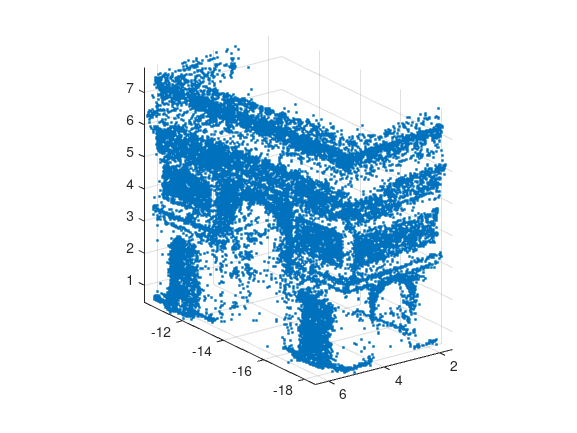

scatter3(Uc(1,:), Uc(2,:), Uc(3,:), '.'), axis equal

Can you recognize the building? 

**Write your answer with explanation as a comment here.**

% I increased the pixel threshold to 10 in order to include more points.
% It's definitely the Arc de Triomphe.

## Least squares triangulation 

In this part of the lab you will solve the tringulation problem through least squares. Just as in the case of registration, the following pipeline is recommended: 

    - Use RANSAC to obtain a rough estimate of the parameters (*U*). 

    - Remove all measurements which are outliers with respect to these parameters. 

    - Estimate the least squares parameters using the remaining measurements. 

Note that in this case a *measurement* is a pair consisting of an image point $u_i$ and a camera matrix $P_i$. Don’t forget that points with negative depths should be outliers. 

**Ex 4.6**     Consider a camera matrix 

                        $P_i =\left\lbrack \begin{array}{c}
\longleftarrow a_i^T \longrightarrow \\
\longleftarrow b_i^T \longrightarrow \\
\longleftarrow c_i^T \longrightarrow 
\end{array}\right\rbrack$ ,

a 3D point *U* and an image point $u_i$. Write the formula for the reprojection error $r_i \left(U\right)$ below.

**Your answer here:**


$$r_i \left(U\right)=$$

$$\left\lbrack \begin{array}{c}
\frac{a_i^T \;U}{c_i^T \;U}-x_{u_i } \\
\frac{b_i^T \;U}{c_i^T \;U}-y_{u_i } 
\end{array}\right\rbrack$$


As you can see, the residuals are no longer linear, so computing a least squares solution will be significantly harder than in the previous lab. In fact, we cannot be sure to find the least squares solution. What we can do is to use local optimization to reduce the sum of squared residuals. We start at the solution produced by Ransac and use a few Gauss-Newton iterations.

**Ex 4.7**     Make a function  

that takes a cell list `Ps` with *N* cameras, a 2 x *N* array `us` of image points and a 3 x 1 array `U`, and computes a 2*N* x 1 array with all the reprojection residuals stacked into a single vector/array. A reprojection residual is a 2D vector corresponding to the difference between the original measurement and the projected point. The stacked vector is the $\bar{r}$ from the lecture notes (page 99).

points3D = triangulation_examples;
all_residuals = compute_residuals(points3D(1).Ps, points3D(1).xs, Us(:,1))

all_residuals =    -5.3580
    0.3999
    1.9444
    0.2039
    3.8158
   -2.4315
    6.7247
    1.2340
    5.3167
   -0.8172


**Ex 4.8**     Find formulas for the partial derivatives in the Jacobian of $\bar{r}$. The Jacobian should be a 2N x 3- matrix. (Hint: you can start by finding the formula to the Jacobian of the i-th residual, which is a 2x3 matrix.)

## Your answer here:


$$J_i =\frac{\partial {\;r}_i \left(U\right)}{\partial \;U}=\left\lbrack \begin{array}{c}
\longleftarrow \frac{a_i^T \;\left(c_i^T \;U\right)-\left(a_i^T \;U\right)\;c_i^T }{{\left(c_i^T \;U\right)}^2 }\longrightarrow \\
\longleftarrow \frac{b_i^T \;\left(c_i^T \;U\right)-\left(b_i^T \;U\right)\;c_i^T }{{\left(c_i^T \;U\right)}^2 }\longrightarrow 
\end{array}\right\rbrack$$


Then, the entire Jacobian would simply be a *stack* of the residuals' Jacobians.

**Ex 4.9**     Make a function 

that computes the Jacobian given a 3 x 1- vector `U` and a cell array of camera matrices `Ps`. 

J = compute_jacobian(points3D(1).Ps, Us(:,1))

J =   -16.9892   73.9682  146.4391
 -161.3389  -16.5013   -7.5054
  -23.9984   75.0513  148.8729
 -162.8907  -25.3457   -9.8102
  -28.2937   70.8752  146.1541
 -158.9337  -32.3169  -10.9875
  -29.1141   69.2071  145.7040
 -156.7436  -38.3195   -8.8389
  -29.7585   69.8099  146.5748
 -156.7145  -42.6233   -7.3311


**Ex 4.10**     Use these functions to make a function 

that uses an approximate 3D point `Uhat` as a starting point for Gauss-Newton’s method. Use five GaussNewton iterations. Print the sum of squared residuals after each Gauss-Newton step to verify that it decreases. 

Uref = refine_triangulation(points3D(1).Ps, points3D(1).xs, Us(:,1))

Uref =   -17.4131
    3.8202
    6.7842


**Ex 4.11**     Try your `refine_triangulation` on the data in `gauss_newton.ma`t. First we will plot the points given in `Uhat`, then refine each point using your function and plot the results using `scatter3`. You should see an improvement. 

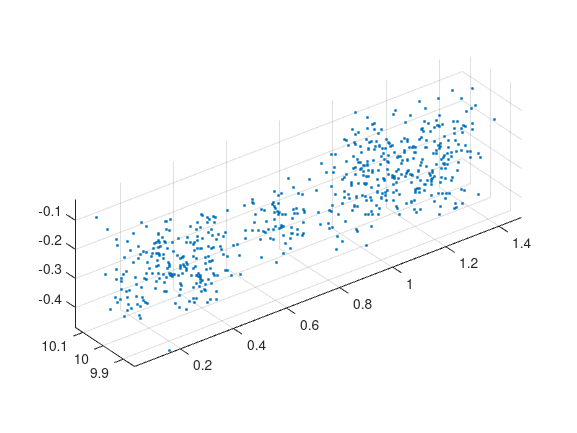

load gauss_newton
scatter3(Uhat(1,:), Uhat(2,:), Uhat(3,:), '.'), axis equal

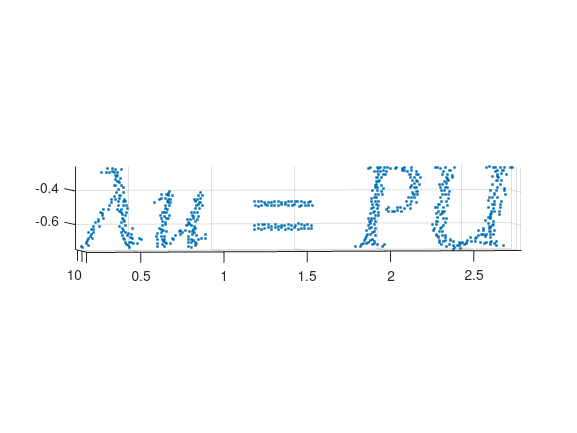

Ps = {P, P_tilde};

N = size(Uhat, 2);
Uref = zeros(3, N);
for i = 1:N
    Uref(:,i) = refine_triangulation(Ps, [u(:,i), u_tilde(:,i)], Uhat(:,1));
end
scatter3(Uref(1,:), Uref(2,:), Uref(3,:),'.'), axis equal

**Ex* 4.12**     Compute the camera positions for the data in `gauss_newton.mat` and plot them together with the estimated 3D points. Try to understand why the noise in the estimated points looks as it does. 

% YOUR CODE HERE; don't forget to plot your results



For the next exercise try the following way to match features, 

The approximate option makes it go significantly faster. A Lowe ratio of 0.9 is very high, but it makes the model more *dens*e. 

**Ex* 4.13**     There are images `duomo.jpg` and `duomo_tilde.jpg` in the lab folder and also a data file `duomo.mat` with two camera matrices. Extract SIFT features from the two images (using `extractSIFT`) and match them using `matchFeatures`. Also store the color of each SIFT point. It doesn’t matter from which of the images you select the color information. 

Use your triangulation code (don’t forget r`efine_triangulation`) to triangulate the points and plot them with the right color using `scatter3`. Again, you can use `clean_for_plot.m` to remove outliers among the estimated 3D points. Beware that triangulating all the points will take a little time so work with a subset until you are sure that the code works. 

%Your code here
load duomo



## **Essential Matrix**

**Ex 4.14**     Load the data in `P.mat`. There you will find two calibrated camera matrices, `P1` and `P2`. Make a function 

that computes the essential matrix `E` from `P1` and `P2` .

load P.mat
P1
P2
E = essentialMatrix(P1, P2)

**Ex* 4.15**     Similar to the reprojection error in the triangulation problem, the essential matrix can also be used for outlier detection using the residual


$$r^2 =\frac{\left|{\tilde{x} }^T \;E\;x\;\right|}{{\left\|S\;E\;x\right\|}^2 +{\left\|S\;E^T \;\;\tilde{x} \right\|}^2 \;},\;\;\;\;\;\;\;\;\;\;S=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$$


where $x$ and $\tilde{x}$ are the image projections of a 3D point *X* using some arbitrary camera matrices $P$ and $\tilde{P}$, respectively. Note that $r$ does not depend on X. Assuming that you are using a similar threshold for outlier detection, for a set of pixel correspondences, you would get `I1` inliers if you use the residual from the triangulation problem and `I2` inliers if you used the residual from (4.4). Which one is greater, `I1` or `I2`? Why? 

P1 =    -0.5763    0.0599   -0.8150    4.8244
    0.3488    0.9199   -0.1791    0.7881
    0.7390   -0.3875   -0.5511    4.8530


P2 =     0.1704   -0.9628   -0.2097    4.7858
   -0.9416   -0.0964   -0.3225    2.4269
    0.2903    0.2525   -0.9230    4.0014


Rt1 =    -0.5763   -0.0599    0.8150
    0.3488   -0.9199    0.1791
    0.7390    0.3875    0.5511


K1 =     1.0000   -0.0000    0.0000
         0   -1.0000   -0.0000
         0         0   -1.0000


K1 =    -1.0000    0.0000   -0.0000
         0    1.0000    0.0000
         0         0    1.0000


K2 =     1.0000   -0.0000         0
         0   -1.0000    0.0000
         0         0    1.0000


P1_norm =     0.5763   -0.0599    0.8150   -4.8244
    0.3488    0.9199   -0.1791    0.7881
    0.7390   -0.3875   -0.5511    4.8530


P2_norm =     0.1704   -0.9628   -0.2097    4.7858
    0.9416    0.0964    0.3225   -2.4269
    0.2903    0.2525   -0.9230    4.0014


E =      0     0     0
     0     0     0
     0     0     0
